# Hyperbolic Tangent under Multisine Excitation

Mauro J. Sanchirico III

This expansion breaks down because it is dependent on taking a taylor series

inside an inverse fourier transform.  The bounds of the inverse fourier transform

integral may not exceed the limits inside of which the taylor series is applicable.

clc; clear; close all;
rng(1);
addpath('./Math');


## Interrogation Signals

% frequencies and periods
omega_vect = [1]';
P_vect = 2*pi./omega_vect;

% Phase shifts - not considered in this analysis
phi_vect = [0]';

% Amplitudes
A_vect = [pi/2]';

% Bias
A0 = 0.0;

% Number of signals
N_s = length(omega_vect) + 1;

% Master period and master frequency
P_M = double(lcm(sym(P_vect)));
omega_M = 2*pi/P_M;

% Time
dt = 0.01;
t = 0:dt:P_M;
t_mat = repmat(t, length(omega_vect), 1);

% Sinusoid argument vector psi
phi_mat = repmat(phi_vect, 1, length(t));
psi_mat = diag(omega_vect)*t_mat + phi_mat;
x_0_mat = diag(A_vect)*sin(psi_mat);

% Append bias signal
A0_vect = ones(1, length(t))*A0;
x_0_mat = [A0_vect; x_0_mat];
t_mat = [t; t_mat];

% Plot interrogation signal properties
figure;

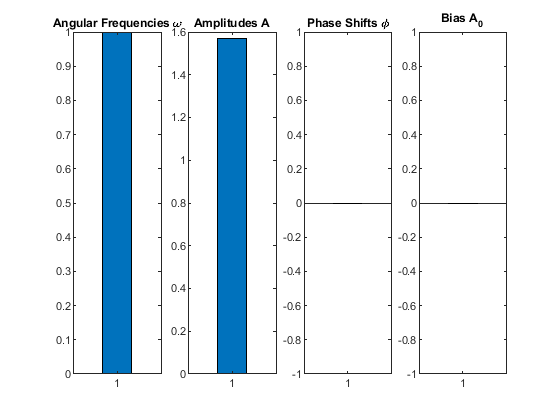

subplot(141);
bar(omega_vect);
title('Angular Frequencies \omega');
subplot(142)
bar(A_vect);
title('Amplitudes A');
subplot(143)
bar(phi_vect);
title('Phase Shifts \phi');
subplot(144)
bar(A0)
title('Bias A_0');

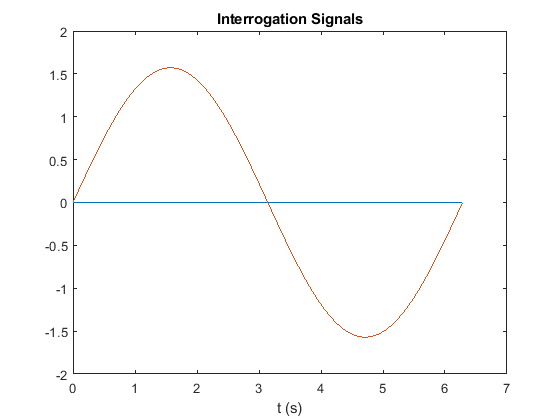


% Plot interrogation signals
figure;
plot(t_mat', x_0_mat');
title('Interrogation Signals');
xlabel('t (s)');

## Hidden Properties

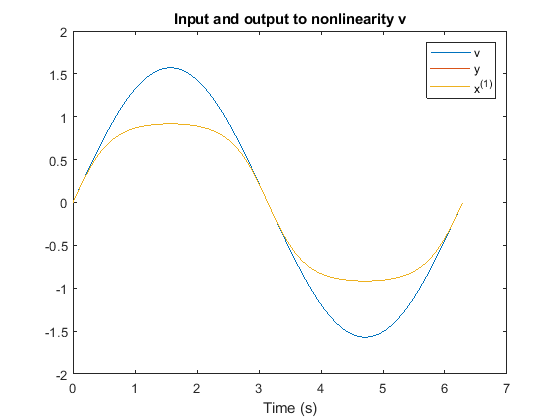

% First layer hidden weights
max_weight = 2;
w_vect_0 = rand(1, N_s)*max_weight;
w_vect_0 = ones(1, N_s);

% Second layer hidden weights
w_vect_1 = rand(1, 1)*max_weight;
w_vect_1 = 1;

% Signal at input to the nonlinearity
v = sum(diag(w_vect_0)*x_0_mat);

% Nonlinearity output
y = tanh(v);

% Output of blackbox
x_1_vect = w_vect_1*y;

% Plot input to nonlinearity
figure;
plot(t, v);
hold on;
plot(t, y);
plot(t, x_1_vect);
title('Input and output to nonlinearity v')
xlabel('Time (s)');
legend('v', 'y', 'x^{(1)}');

## Analyze the Output Signal Numerically

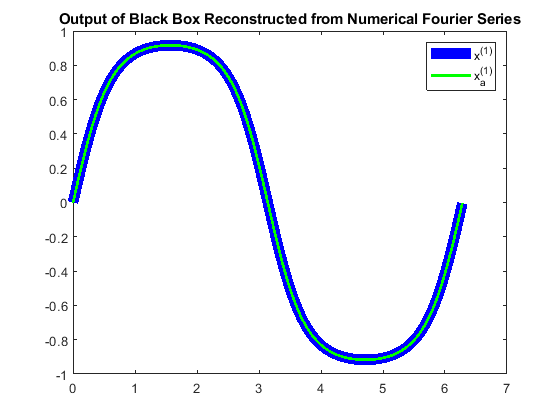

N_f = 30;
[a, b, ~, n] = ComputeNumericalFourierSeries(t, x_1_vect, N_f);

x_1_vect_approx = ComputeReconstructedFunctionFromFourierSeries(a, b, n, t);

figure;
plot(t, x_1_vect, 'b', 'linewidth', 8);
hold on;
plot(t, x_1_vect_approx, 'g', 'linewidth', 2);
title('Output of Black Box Reconstructed from Numerical Fourier Series')
legend('x^{(1)}', 'x^{(1)}_a');

## Analyze the Output Signal Analytically - Part 1

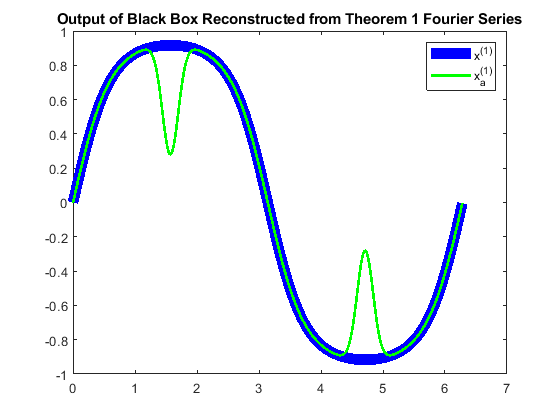

% Compute the Fourier Series using Theorem 1
gamma_1 = w_vect_1;
N_f = 30;
N_t = 30;
[a, b, c, n] = ComputeTheorem1FourierSeries(t, v, N_f, N_t, gamma_1);
x_1_vect_approx = ComputeReconstructedFunctionFromFourierSeries(a, b, n, t);

figure;
plot(t, x_1_vect, 'b', 'linewidth', 8);
hold on;
plot(t, x_1_vect_approx, 'g', 'linewidth', 2);
title('Output of Black Box Reconstructed from Theorem 1 Fourier Series')
legend('x^{(1)}', 'x^{(1)}_a');